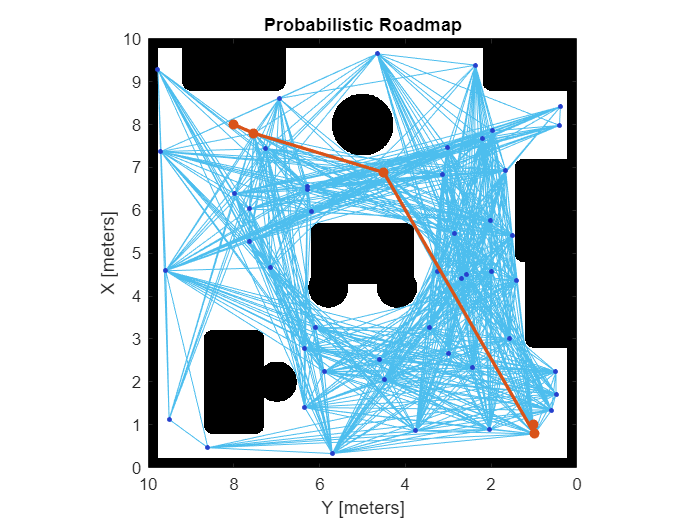

% Generate a path
% Use PRM

if ~exist('binary_map','var')
    define_binary_map;
end

p_start = [1 1];
p_end = [8 8];


prm = mobileRobotPRM(binary_map_inflated);
xy = findpath(prm,p_start,p_end);

show(prm)
view(-90,90);

% Generate a time trajectory
N = 1e3+1

N = 1001

[xy_des,~,~,tt,~] = trapveltraj(xy',N)

xy_des =     1.0000    1.0000    1.0000    0.9999    0.9999    0.9998    0.9997    0.9996    0.9995    0.9994    0.9992    0.9991    0.9989    0.9987    0.9985    0.9982    0.9980    0.9977    0.9975    0.9972    0.9969    0.9965    0.9962    0.9959    0.9955    0.9951    0.9947    0.9943    0.9939    0.9934    0.9929    0.9925    0.9920    0.9915    0.9909    0.9904    0.9898    0.9893    0.9887    0.9881    0.9875    0.9868    0.9862    0.9855    0.9848    0.9841    0.9834    0.9827    0.9819    0.9812
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9999    0.9998    0.9998    0.9998    0.9998    0.9998    0.9998    0.9997    0.9997    0.9997    0.9997    0.9996    0.9996    0.9996    0.9996    0.9995    0.9995    0.9995    0.9995    0.9994    0.9994    0.9994    0.9993    0.9993    0.9993    0.9992    0.9992    0.9992    0.9991    0.9991

tt =          0    0.0040    0.0080    0.0120    0.0160    0.0200    0.0240    0.0280    0.0320    0.0360    0.0400    0.0440    0.0480    0.0520    0.0560    0.0600    0.0640    0.0680    0.0720    0.0760    0.0800    0.0840    0.0880    0.0920    0.0960    0.1000    0.1040    0.1080    0.1120    0.1160    0.1200    0.1240    0.1280    0.1320    0.1360    0.1400    0.1440    0.1480    0.1520    0.1560    0.1600    0.1640    0.1680    0.1720    0.1760    0.1800    0.1840    0.1880    0.1920    0.1960


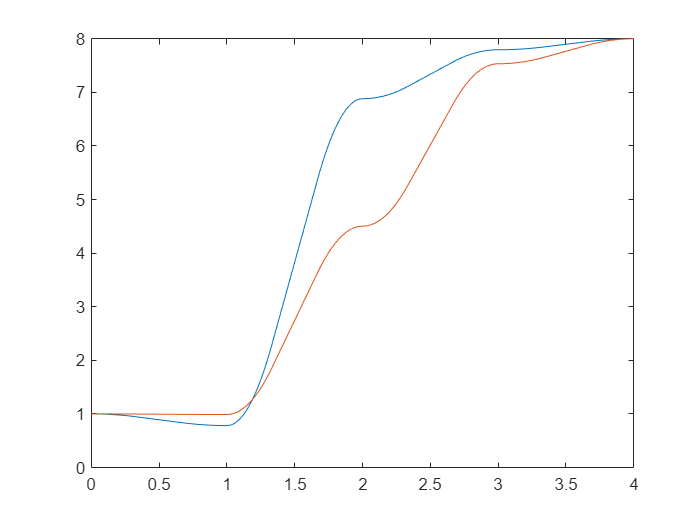


plot(tt, xy_des)

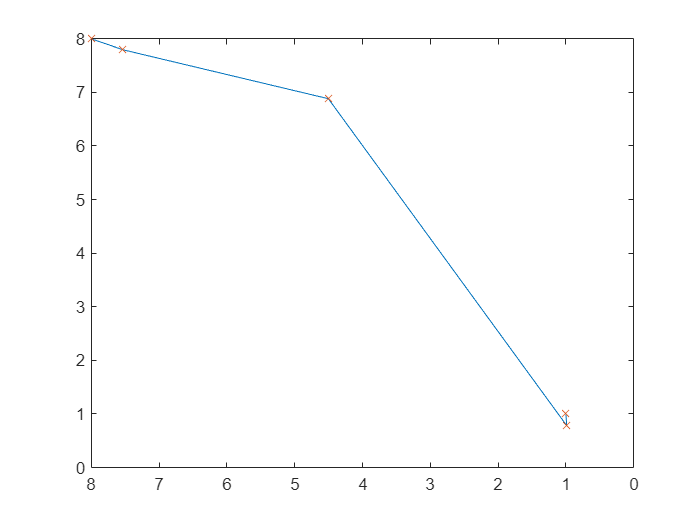

plot(xy_des(1,:), xy_des(2,:)); hold on
plot(xy(:,1), xy(:,2), 'x'); hold off
view(-90,90);

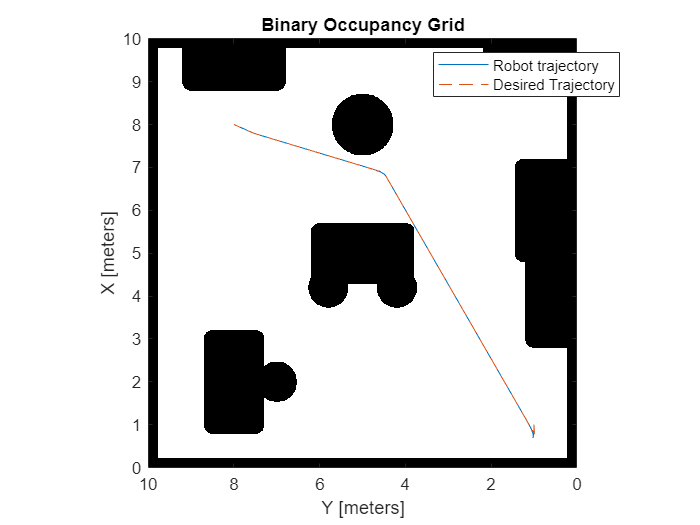

% Follow the path
robot_state_hist = NaN(3, N);
robot_state_hist(:,1) = [p_start 0]';
T = mean(diff(tt));
for i = 1: N-1
    u = nonholonomic_control(robot_state_hist(:,i), xy_des(:,i));
    v = robot_model(robot_state_hist(:,i), u);
    robot_state_hist(:,i+1) = robot_state_hist(:,i) + v * T;
end

show(binary_map_inflated); hold on
plot(robot_state_hist(1,:), robot_state_hist(2,:));
%plot(xy_des(1,:), xy_des(2,:));
plot(xy(:,1), xy(:,2), '--'); 
hold off
view(-90,90);
legend("Robot trajectory", "Desired Trajectory", Location="northeast")

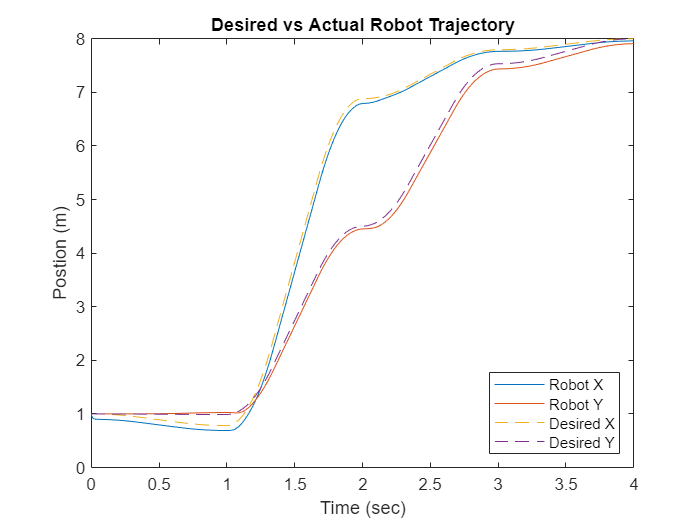


plot(tt, robot_state_hist(1:2,:)'); hold on
plot(tt, xy_des', '--'); hold off
legend(["Robot X" "Robot Y" "Desired X" "Desired Y"], Location="southeast")
xlabel("Time (sec)")
ylabel("Postion (m)")
title("Desired vs Actual Robot Trajectory")

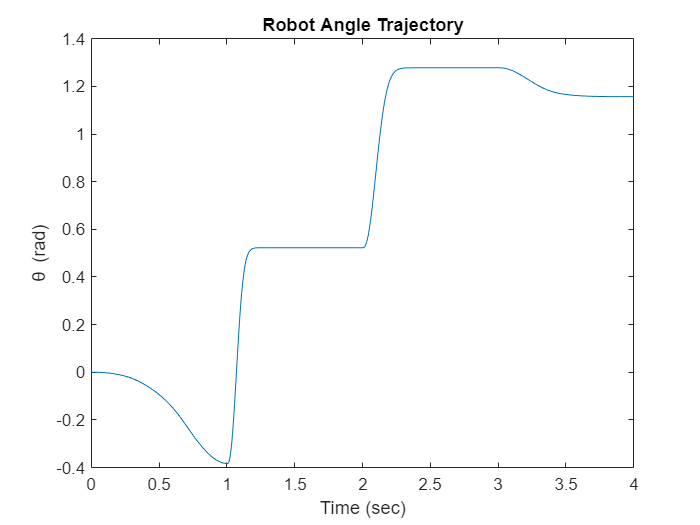



plot(tt, robot_state_hist(3,:))
xlabel("Time (sec)")
ylabel("\theta (rad)")
title("Robot Angle Trajectory")

function u = nonholonomic_control(state, xy_des)
p_x = 0.1;
p_y = 0;
k_p = 100;

J = rot2(state(3))*[1 -p_y; 0 p_x];

% Convert from robot frame to offset frame
os_xy = state(1:2) + rot2(state(3)) * [p_x; p_y];

% Find error
e_xy = xy_des - os_xy;

% Offset velocity
v_os = k_p*e_xy;

% Convert to robot velocity
u = inv(J) * v_os;
end

function v = robot_model(state, u)
v = NaN([3 1]);

v(1)=u(1)*cos(state(3));
v(2)=u(1)*sin(state(3));
v(3)=u(2);

end